# College Tuition

### College tuition data for 2 and 4 year institutions, and salary potential for colleges by rank within their region.

Original Kaggle dataset: [https://www.kaggle.com/jessemostipak/college-tuition-diversity-and-pay](https://www.kaggle.com/jessemostipak/college-tuition-diversity-and-pay) This link has the column descriptions for the data. We've provided the data from the tuition_cost.csv file and the salar_potential.csv file. Note that in tuition_cost.csv (now college_tuition.mat), we changed "2 year" and "4 year" to 2 and 4 (numeric) to make it easier to work with in MATLAB.

Check out the documentation on the MATLAB website re: graphing categorical data: [https://www.mathworks.com/help/matlab/matlab_prog/plot-categorical-data.html](https://www.mathworks.com/help/matlab/matlab_prog/plot-categorical-data.html)

# Your code here

Feel free to insert more code blocks here

% loads file
load college_salary.mat

# Average Salary for Each State


% Collects data for Mid Salary & States
states_num = salary_mat_strs(:, 2);
mid_salary = salary_mat_nums(:, 3);

% Sorted list of state names
state_name = sort(unique(states_num));

% This is to make an array size 50
% This just makes the code more efficient (not needed)
average_sal = zeros(50, 1);

% The for loop goes from 1 to 50 (for j)
% for every state
% The for loop resets i and total for every state
for j=1:50
    % i is the entry for every entry (goes from 1-935)
    i = 1;
    % Total is used to calc average
    total = 0;
    
    % This is only for Alabama
    if state_name(j) == states_num(i)
        while state_name(j) == states_num(i)
            total = total + mid_salary(i);
            i = i + 1;
        end
        % This is needed to correct offset
        i = i - 1;
        
        % Calculates average and adds it to
        % the list average_sal
        avg = total / i;
        average_sal(j) = avg;
    else
        % For every state other than Alabama
        
        % What is being done is that this first loop
        % skips every entry until the state_name
        % matches with the entry
        while state_name(j) ~= states_num(i)
            i = i + 1;
            if state_name(j) == states_num(i)
                
                sub_amount = i;
                
                % This while loop actually does the work
                while i < 936 && state_name(j) == states_num(i)
                    total = total + mid_salary(i);
                    i = i + 1;
                end
                
                % The subamount is to correct an offset
                % Sort of like setting total back to 0
                i = i - (sub_amount);
                avg = total / i;
                average_sal(j) = avg;
                break
            end
        end
    end
end

# Average Career Salary by State

color_sal = zeros(50, 2);
 
% New list of States
states_num = ["Alaska","Alabama","Arkansas","Arizona","California","Colorado",...
   "Connecticut","Delaware","Florida","Georgia","Hawaii","Iowa","Idaho","Illinois",...
   "Indiana","Kansas","Kentucky","Louisiana","Massachusetts","Maryland","Maine",...
   "Michigan","Minnesota","Missouri","Mississippi","Montana","North Carolina",...
   "North Dakota","Nebraska","New Hampshire","New Jersey","New Mexico","Nevada",...
   "New York","Ohio","Oklahoma","Oregon","Pennsylvania","Rhode Island",...
   "South Carolina","South Dakota","Tennessee","Texas","Utah","Virginia",...
   "Vermont","Washington","Wisconsin","West Virginia","Wyoming"]

states_num = 1×50 string array
    "Alaska"    "Alabama"    "Arkansas"    "Arizona"    "California"    "Colorado"    "Connecticut"    "Delaware"    "Florida"    "Georgia"    "Hawaii"    "Iowa"    "Idaho"    "Illinois"    "Indiana"    "Kansas"    "Kentucky"    "Louisiana"    "Massachusetts"    "Maryland"    "Maine"    "Michigan"    "Minnesota"    "Missouri"    "Mississippi"    "Montana"    "North Carolina"    "North Dakota"    "Nebraska"    "New Hampshire"    "New Jersey"    "New Mexico"    "Nevada"    "New York"    "Ohio"    "Oklahoma"    "Oregon"    "Pennsylvania"    "Rhode Island"    "South Carolina"    "South Dakota"    "Tennessee"    "Texas"    "Utah"    "Virginia"    "Vermont"    "Washington"    "Wisconsin"    "West Virginia"    "Wyoming"


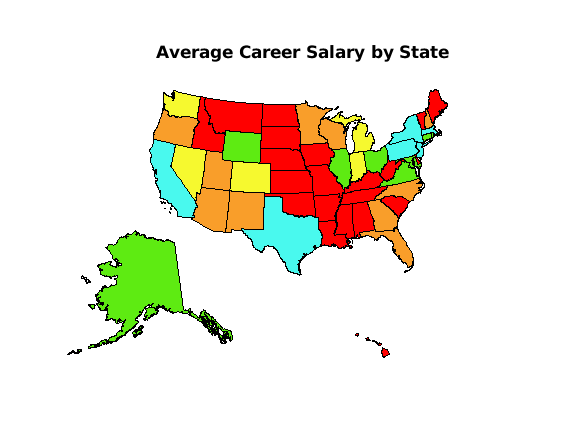

 
state_name = sort(unique(states_num)); % Sorted List of States
 
% Needed for US Map
figure
ax = usamap('all');
set(ax, 'Visible', 'off')
states = shaperead('usastatelo', 'UseGeoCoords', true);
names = {states.Name};
indexHawaii = strcmp('Hawaii',names);
indexAlaska = strcmp('Alaska',names);
 
for i=1:50
   if average_sal(i) > 100000 % Blue
       color = [0.286,0.976,0.933]; 
   elseif average_sal(i) > 95000 % Green
       color = [0.369,0.923,0.071]; 
   elseif average_sal(i) > 93000 % Yellow
       color = [0.964, 0.976, 0.184]; 
   elseif average_sal(i) > 88000 % Orange
       color = [0.976, 0.620, 0.165]; 
   else % Red
       color = [1,0, 0];
    end
   
    if i == 2
       geoshow(ax(2), states(indexAlaska), 'FaceColor', color)
   elseif i == 11
       geoshow(ax(3), states(indexHawaii), 'FaceColor', color)
   end
   geoshow(shaperead('usastatehi', 'UseGeoCoords', true,...
       'Selector',{@(name) strcmpi(name,state_name(i)), 'Name'}),...
       'FaceColor', color)
end
 
for k = 1:3
   setm(ax(k), 'Frame', 'off', 'Grid', 'off',...
       'ParallelLabel', 'off', 'MeridianLabel', 'off')
end
title('Average Career Salary by State','FontWeight','bold', 'FontSize',12, 'FontName','Times New Roman');
save('usmap.png')

save('usmap.jpg')


# Profit, Public, Private, Price??

%load college_tuition.mat

%tuition = (tuition_mat_nums(:, 4) + tuition_mat_nums(:, 6))/2


%tuition_public = tuition(tuition_mat_strs(:, 4) == "Public")
%tuition_private = tuition(tuition_mat_strs(:, 4) == "Private")
%tuition_profit = tuition(tuition_mat_strs(:, 4) == "For Profit")

%boxplot(tuition_public, "Orientation", "horizontal")
%boxplot(tuition_private, "Orientation", "horizontal")
%boxplot(tuition_profit, "Orientation", "horizontal")

%figure
%boxplot([tuition_public, tuition_private, tuition_profit], "Orientation", "horizontal")

# In-state Out-state Tuition Heat Map

% New list of States
states_num = ["Alaska","Alabama","Arkansas","Arizona","California","Colorado",...
    "Connecticut","Delaware","Florida","Georgia","Hawaii","Iowa","Idaho","Illinois",...
    "Indiana","Kansas","Kentucky","Louisiana","Massachusetts","Maryland","Maine",...
    "Michigan","Minnesota","Missouri","Mississippi","Montana","North Carolina",...
    "North Dakota","Nebraska","New Hampshire","New Jersey","New Mexico","Nevada",...
    "New York","Ohio","Oklahoma","Oregon","Pennsylvania","Rhode Island",...
    "South Carolina","South Dakota","Tennessee","Texas","Utah","Virginia",...
    "Vermont","Washington","Wisconsin","West Virginia","Wyoming"]

states_num = 1×50 string array
    "Alaska"    "Alabama"    "Arkansas"    "Arizona"    "California"    "Colorado"    "Connecticut"    "Delaware"    "Florida"    "Georgia"    "Hawaii"    "Iowa"    "Idaho"    "Illinois"    "Indiana"    "Kansas"    "Kentucky"    "Louisiana"    "Massachusetts"    "Maryland"    "Maine"    "Michigan"    "Minnesota"    "Missouri"    "Mississippi"    "Montana"    "North Carolina"    "North Dakota"    "Nebraska"    "New Hampshire"    "New Jersey"    "New Mexico"    "Nevada"    "New York"    "Ohio"    "Oklahoma"    "Oregon"    "Pennsylvania"    "Rhode Island"    "South Carolina"    "South Dakota"    "Tennessee"    "Texas"    "Utah"    "Virginia"    "Vermont"    "Washington"    "Wisconsin"    "West Virginia"    "Wyoming"



% All the needed 2-D arrays for the for loops
state_name = sort(unique(states_num));
state_in_tuition = zeros(50, 1);
state_out_tuition = zeros(50, 1);

sum_in_tuition = zeros(50, 1);
sum_out_tuition = zeros(50, 1);

ratio_tuition = zeros(50, 1);

% Gets in-state tuition for each state
for i=1:2972
    for j=1:50
        if tuition_mat_strs(i, 2) == state_name(j)
            state_in_tuition(j, i) = tuition_mat_nums(i, 4);
        end
    end
end

% Gets out-state tuition for each state
for i=1:2972
    for j=1:50
        if tuition_mat_strs(i, 2) == state_name(j)
            state_out_tuition(j, i) = tuition_mat_nums(i, 6);
        end
    end
end

% Sums up that tuition for each state (in-state)
for i=1:50
    sum_in_tuition(i, 2) = sum(state_in_tuition(i, 2:end));
end

% Out-state
for i=1:50
    sum_out_tuition(i, 2) = sum(state_out_tuition(i, 2:end));
end

% Finds ratios
for i=1:50
    ratio_tuition(i, 2) = sum_out_tuition(i, 2) / sum_in_tuition(i, 2);
end


shows_states = sort(tuition_mat_strs(:, 2));
state_count = zeros([50,1]);


for j=1:50
    for i=1:2972
        if state_name(j) == shows_states(i) 
            state_count(j) = state_count(j)+1;
           % disp(state_count);
            
        end
        
    end
  
end

x = sum_in_tuition (:, 2) ./ state_count;

%hold on

scatter(x,average_sal, "MarkerFaceColor", "red")

xlabel('Average State Tuition')
ylabel('Average State Salary')

%xlim([0,500000])
%coeffs = polyfit(x, average_sal, 1); %1 means you are 

%m = coeffs(1);
%b = coeffs(2);


%Finally, plot the line of best fit!
%%x = linspace(0,5, n_points); 
%y = x*coeffs(1) + coeffs(2);

%hold on
%plot(x,y)
hold off

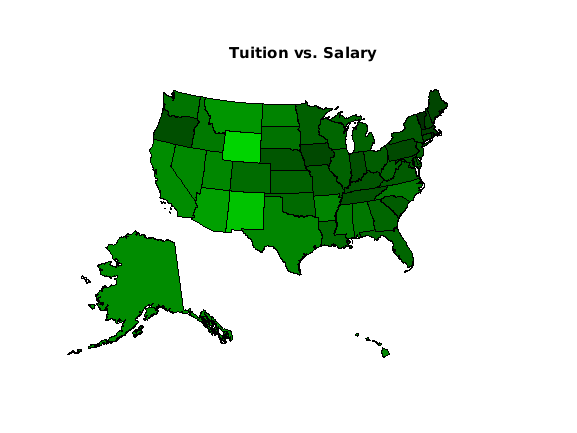

%Extra
ratio_salary = zeros(50, 1);
for i=1:50
    ratio_salary(i) = average_sal(i) ./ x(i);
end


%ratio_salary = average_sal / x;
% List of colors
percent_color1 = ratio_salary(:) / 9.375;

% Stuff I copied for the documentation and don't understand
figure
ax = usamap('all');
set(ax, 'Visible', 'off')
states = shaperead('usastatelo', 'UseGeoCoords', true);
names = {states.Name};
indexHawaii = strcmp('Hawaii',names);
indexAlaska = strcmp('Alaska',names);

% This loop apllys the right colors for each state
for i=1:50
    if i == 2
        geoshow(ax(2), states(indexAlaska), 'FaceColor', [0, percent_color1(i)/1.2, 0])
    elseif i == 11
        geoshow(ax(3), states(indexHawaii), 'FaceColor', [0, percent_color1(i)/1.2, 0])
    end
    geoshow(shaperead('usastatehi', 'UseGeoCoords', true,...
        'Selector',{@(name) strcmpi(name,state_name(i)), 'Name'}),...
        'FaceColor', [0, percent_color1(i)/1.2, 0])
end






for k = 1:3
    setm(ax(k), 'Frame', 'off', 'Grid', 'off',...
        'ParallelLabel', 'off', 'MeridianLabel', 'off')
end

title('Tuition vs. Salary')

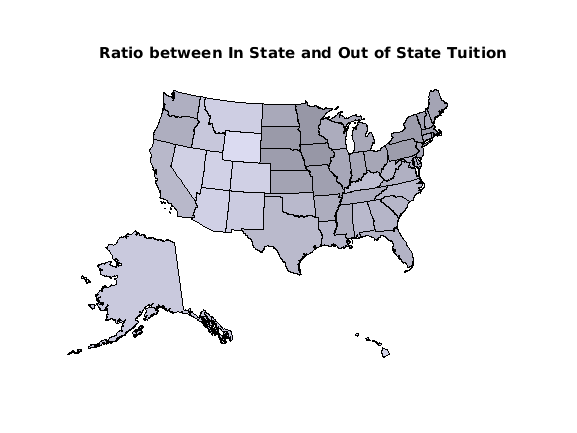

% List of colors
percent_color = ratio_tuition(:, :) / 1.4599;

% Stuff I copied for the documentation and don't understand
figure
ax = usamap('all');
set(ax, 'Visible', 'off')
states = shaperead('usastatelo', 'UseGeoCoords', true);
names = {states.Name};
indexHawaii = strcmp('Hawaii',names);
indexAlaska = strcmp('Alaska',names);
indexConus = 1:numel(states);
indexConus(indexHawaii|indexAlaska) = [];
stateColor = [0.5 1 0.5];

% This loop apllys the right colors for each state
for i=1:50
    if i == 2
        geoshow(ax(2), states(indexAlaska), 'FaceColor', [percent_color(i, 2)/1.1, percent_color(i, 2)/1.1, percent_color(i, 2)]/1.1)
    elseif i == 11
        geoshow(ax(3), states(indexHawaii), 'FaceColor', [percent_color(i, 2)/1.1, percent_color(i, 2)/1.1, percent_color(i, 2)]/1.1)
    end
    geoshow(shaperead('usastatehi', 'UseGeoCoords', true,...
        'Selector',{@(name) strcmpi(name,state_name(i)), 'Name'}),...
        'FaceColor', [percent_color(i, 2)/1.1, percent_color(i, 2)/1.1, percent_color(i, 2)]/1.1)
end






for k = 1:3
    setm(ax(k), 'Frame', 'off', 'Grid', 'off',...
        'ParallelLabel', 'off', 'MeridianLabel', 'off')
end

title('Ratio between In State and Out of State Tuition')

hold off


shows_states = sort(tuition_mat_strs(:, 2));
state_count = zeros([50,1])

state_count =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0




for j=1:50
    for i=1:2972
        if state_name(j) == shows_states(i) 
            state_count(j) = state_count(j)+1;
            disp(state_count)
            
        end
        
    end
  
end

     1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0

     2
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0

     3
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
    

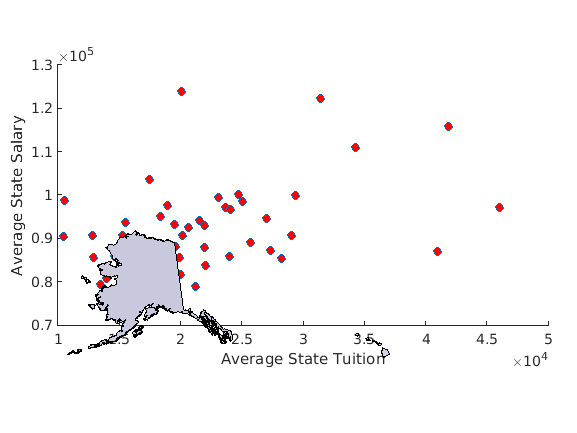


x = sum_in_tuition (:, 2) ./ state_count;

%hold on

scatter(x,average_sal, "MarkerFaceColor", "red")

xlabel('Average State Tuition')
ylabel('Average State Salary')


%xlim([0,500000])
%coeffs = polyfit(x, average_sal, 1); %1 means you are 

%m = coeffs(1);
%b = coeffs(2);


%Finally, plot the line of best fit!
%n_points = 100;
%x = linspace(0,8, n_points); 
%y = x*coeffs(1) + coeffs(2);


%plot(x,y, "r--")